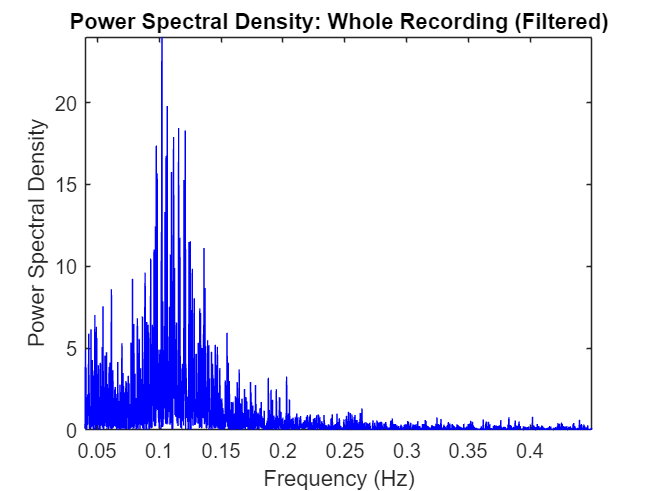

% Load the data
load('Placeholder.mat');
fs = 1000;  % Sampling frequency

% High-pass filter parameters
cutoff_frequency = 0.5;  % Cut-off frequency
order = 2;  % Filter order

% Design a Butterworth high-pass filter
[B, A] = butter(order, cutoff_frequency/(fs/2), 'high');

% Apply the filter to the data
filtered_data = filtfilt(B, A, data);

% Find peaks in the filtered data
% Adjust 'MinPeakDistance' as needed for your specific dataset
[PKS, LOCS] = findpeaks(filtered_data, 'MinPeakDistance', 525); 

% Compute differences between consecutive peak locations
dLOCS = diff(LOCS);

% Compute and plot Lomb-Scargle Periodogram for the filtered data
% Scale times by 10^-3 to convert from milliseconds to seconds for 'plomb'
[P, F] = plomb(dLOCS, LOCS(2:end) * 10^-3, 'normalized');

% Plot the Periodogram for the whole dataset
figure;
plot(F, P, 'b-');
title('Power Spectral Density: Whole Recording (Filtered)');
xlabel('Frequency (Hz)'); 
ylabel('Power Spectral Density');
xlim([0.04, 0.45]); % Adjust these limits based on the frequencies of interest
ylim([0, 24]); % Adjust these limits based on the PSD values observed


% Note: The 'MinPeakDistance' is a parameter for the findpeaks function to ensure accurate peak detection.
% Adjust it based on the expected HRV or peak frequency in your data.
